## Cluster-based permutations

Mathilde Marie Duville

**Notice:** please, run the codes for figures in the command window to output them with a correct scale for visualization

### General concepts

The cluster-based permutation approach is a non-parametric method that allows to relate statistical effects to 2- or 3-dimensional windows (channel × frequency × time, channel × time or channel × frequency, according to the neuronal marker of interest). Each window is name a cluster.

In particular, effects are computed within the 2- or 3-dimensional matrix at each sample, for which a test statistic is computed and compared to the critical threshold (e.g., p-value < 0.05). Adjacent samples with statistics exceeding the threshold are grouped within a cluster. Temporal and/or spectral vicinity are trivially established, and clusters may be composed of 1 o more neighboring sensors. Then, a cluster-level statistic is defined as for instance, the sum of statistics within every cluster. 

The inferential stage may be established by the Monte-Carlo estimate with random permutations (~1000 in general) under the null hypothesis of exchangeability. For every iteration, the cluster-formation stage is repeated, and the maximum cluster-level statistic is stored to build a distribution. 

The cluster-level statistic defined from the observed data (not from the Monte-Carlo process) is further located on the empirical distribution. The percentage of permutations that leads to a larger statistic is the p-value considered to assess the effect. Therefore, because a single value (the cluster-level statistic) whose probability under the null hypothesis is considered instead of the 2- or 3-dimensional matrix, multiple comparison issues are exempted, and the statistical output can be related to the cluster window. 

However, when cluster-based permutation tests are repeated (for post hoc comparisons for instance), p-values must be corrected (for instance with the Bonferroni method). Also, the significance must adjusted for two-sided tests (p-value < 0.025).

**Please, refer to the PowerPoint slide dedicated to it for a visual explanation (TheoreticalExplanations.pdf).**

### The present analysis

Here, the cluster-based permutations approach is applied to perform a mixed within-between two-way ANOVA. The effects of variable Emotion (Anger versus Happiness) and variable Group (Neurotypical or NT versus Autism Spectrum Disorder or ASD) are assessed on event-related spectral perturbations (ERSP; time-frequency analysis). Please refere to the mlx. document "*TimeFrequency*" for a detailed explanation and codes for extracting ERSP.

Specifically, a group × emotion Analysis of Variance (ANOVA) with “emotion” as the repeated (within) factor, and “group” as the independent (between) factor is implemented. The effect of the interaction between factors is also assessed between groups and emotions. 

**Note: Please, see the R code "*****ANOVA*****" for details about the methodology to assess post-hoc simple main effects (assessing the effect of one factor at each modality of the other factor) and pairwise comparisons when adequate. In the present document, only the Matlab code ligns for cluster-based permutations are provided. Refer to the R codes for more details about the statistical methodology of the ANOVA. **

#### Load the data

Note: Here, only 15 participants are included to reduce computation time. Please, proceed to a priori power analysis beforehand to establish the number of participants needed.

% Significant from baseline ERSP
% Cell of size channels x participants
% Each cell is of size frequencies x time
clc; clear; close all;
AngerNT = importdata('AngerNT.mat'); AngerASD = importdata('AngerASD.mat'); 
HappinessNT = importdata('HappinessNT.mat'); HappinessASD = importdata('HappinessASD.mat'); 

% part x electrodes x freq x time
% For group effect
EmotionsNT = permute([AngerNT, HappinessNT], [2 3 1 4]);
EmotionsASD = permute([AngerASD, HappinessASD], [2 3 1 4]);

% For emotion effect
Anger=permute([AngerNT, AngerASD], [2 3 1 4]);
Happiness=permute([HappinessNT, HappinessASD], [2 3 1 4]);

% For interaction 
NT = permute(AngerNT-HappinessNT, [2 3 1 4]); ASD = permute(AngerASD-HappinessASD, [2 3 1 4]);

AngerNT = []; HappinessNT = []; AngerASD = []; HappinessASD = []; 

Emotion effect

% Create structure for permutation in Fieldtrip
load('chanlocs.mat'); load('frequencies.mat');load('time.mat');
% Anger
Anger_IntEffect = struct; 
Anger_IntEffect.label = ({chanlocs.labels}');
Anger_IntEffect.freq = frequencies;
Anger_IntEffect.time = times/1000; %in sec
Anger_IntEffect.dimord = 'subj_chan_freq_time';
Anger_IntEffect.powspctrm = Anger;

% Happiness
Happiness_EmotionEffect = struct; 
Happiness_EmotionEffect.label = ({chanlocs.labels}');
Happiness_EmotionEffect.freq = frequencies;
Happiness_EmotionEffect.time = times/1000; %in sec
Happiness_EmotionEffect.dimord = 'subj_chan_freq_time';
Happiness_EmotionEffect.powspctrm = Happiness;

% Add Fieldtrip path 
addpath(PathToFieldtrip); ft_defaults; % [~,ftpath] = ft_version;

% A structure containing information about neighbouring channels
% Can be prepared by ft_prepare_neighbours
neighbours = importdata((strcat(PathToFieldtrip,'\template\neighbours\elec1010_neighb.mat')));

% Create a FieldTrip style 'design'-matrix
% Information about the design of the study. Here the "Emotion" variable is
% repeated within participants. Therefore, it must be specified in the 2nd
% row: the number of the condition (here 1 for Anger and 2 for Happiness)
% must be repeated across participants. Participants are specified in the
% 1st row. 
subj = size(Anger,1); nb_cond = 2; %number of conditions to compare
design = []; design = zeros(2,nb_cond*subj); 
for i = 1:subj
  design(1,i) = i;
end

for i = 1:subj
  design(1,subj+i) = i;
end

design(2,1:subj)  = 1; design(2,subj+1:2*subj) = 2;

% See the variable to check
design

design =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


% Configure the structure to compute statistics
cfg = []; cfg.channel = {'all'}; %consider all channels available

cfg.method='montecarlo';% Monte-Carlo estimate

cfg.statistic='ft_statfun_depsamplesT'; %Specify the test (corresponding Fieldtrip function)
% ft_statfun_depsamplesFunivariate for Anova

cfg.correctm='cluster'; %Method to correct for multiple comparisons, here, cluster-based statitic

cfg.clusterthreshold='nonparametric_common'; %Method for single-sample threshold during Monte-Carlo

cfg.clusteralpha=0.05; %alpha value used to compute sample-specific statistics

cfg.clusterstatistic='maxsum'; %cluster statistic (here, the maximum cluster-level statistic is stored to build a distribution) 
% and the cluster-level statistic is defined as the sum of statistics
% within every cluster

cfg.minnbchan=1; %Minimum number of neighbourhood channels required to be included in a cluster (at the scale of the sample whose statistics is above the significant threshold)

cfg.tail=0; %0 for t-test (two tails); 1 for F test (right tail); -1 (left tail)

cfg.clustertail=0;  %0 for t-test (two tails); 1 for F test (right tail);  -1 (left tail)

cfg.alpha=0.025;% .05/2 when two-sided - critical value to define the p-value
% The percentage of permutations that leads to a larger statistic is the p-value (defined by cfg.alpha) considered to assess the effect. 

cfg.numrandomization=1000; %number of random permutations during the Monte-Carlo process

cfg.neighbours=neighbours; cfg.design=design;
cfg.uvar= 1; %unit and variable that creates the dependency between samples (participants in first row of the design)
cfg.ivar= 2; %independent conditions (anger vs happiness)
cfg.frequency = 'all'; %consider all frequencies
cfg.latency  = [0 1.446]; % time interval over which the experimental conditions must be compared (in seconds)                                                      

% Run the analysis
% In case of time  previous time-locked analysis (e.g., event-related
% potentials), use ft_timelockstatistics instead of ft_freqstatistics
EmotionEffect=ft_freqstatistics(cfg,Anger_IntEffect,Happiness_EmotionEffect);  

the call to "ft_selectdata" took 0 seconds
using specified neighbours for the channels
there are on average 7.9 neighbours per channel
the call to "ft_prepare_neighbours" took 0 seconds
using "ft_statistics_montecarlo" for the statistical testing
using "ft_statfun_depsamplesT" for the single-sample statistics
constructing randomized design
total number of measurements     = 60
total number of variables        = 2
number of independent variables  = 1
number of unit variables         = 1
number of within-cell variables  = 0
number of control variables      = 0
using a permutation resampling approach
repeated measurement in variable 1 over 30 levels
number of repeated measurements in each level is 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 
the maximum number of unique permutations is 1073741824
generated 1000 random permutations
using a nonparametric threshold for clustering
computing statistic
estimated time per randomization is 0.30 seconds
computing statistic 1000 fro


save EmotionEffect EmotionEffect

Group effect (NT vs ASD)

% Create structure for permutation in Fieldtrip
load('chanlocs.mat'); load('frequencies.mat');load('time.mat');
% NT
NT_GroupEffect = struct; 
NT_GroupEffect.label = ({chanlocs.labels}');
NT_GroupEffect.freq = frequencies;
NT_GroupEffect.time = times/1000; %in sec
NT_GroupEffect.dimord = 'subj_chan_freq_time';
NT_GroupEffect.powspctrm = EmotionsNT;

% ASD
ASD_GroupEffect = struct; 
ASD_GroupEffect.label = ({chanlocs.labels}');
ASD_GroupEffect.freq = frequencies;
ASD_GroupEffect.time = times/1000; %in sec
ASD_GroupEffect.dimord = 'subj_chan_freq_time';
ASD_GroupEffect.powspctrm = EmotionsASD;


% Create a FieldTrip style 'design'-matrix
% Information about the design of the study. 

% Here the "Group" variable is NOT
% repeated within participants. Therefore, only the conditions must be
% specified in the design variable that must be of a single row.

design = zeros(1,size(NT_GroupEffect.powspctrm,1) + size(ASD_GroupEffect.powspctrm,1));
design(1,1:size(NT_GroupEffect.powspctrm,1)) = 1;
design(1,(size(NT_GroupEffect.powspctrm,1)+1):(size(NT_GroupEffect.powspctrm,1)+...
size(ASD_GroupEffect.powspctrm,1))) = 2;


% See the variable to check
design

design =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


% Configure the structure to compute statistics
cfg = []; cfg.channel = {'all'}; %consider all channels available

cfg.method='montecarlo';% Monte-Carlo estimate

cfg.statistic='ft_statfun_indepsamplesT'; %Specify the test (corresponding Fieldtrip function)
% ft_statfun_depsamplesFunivariate for Anova

cfg.correctm='cluster'; %Method to correct for multiple comparisons, here, cluster-based statitic

cfg.clusterthreshold='nonparametric_common'; %Method for single-sample threshold during Monte-Carlo

cfg.clusteralpha=0.05; %alpha value used to compute sample-specific statistics

cfg.clusterstatistic='maxsum'; %cluster statistic (here, the maximum cluster-level statistic is stored to build a distribution) 
% and the cluster-level statistic is defined as the sum of statistics
% within every cluster

cfg.minnbchan=1; %Minimum number of neighbourhood channels required to be included in a cluster (at the scale of the sample whose statistics is above the significant threshold)

cfg.tail=0; %0 for t-test (two tails); 1 for F test (right tail); -1 (left tail)

cfg.clustertail=0;  %0 for t-test (two tails); 1 for F test (right tail);  -1 (left tail)

cfg.alpha=0.025;% .05/2 when two-sided - critical value to define the p-value
% The percentage of permutations that leads to a larger statistic is the p-value (defined by cfg.alpha) considered to assess the effect. 

cfg.numrandomization=1000; %number of random permutations during the Monte-Carlo process

cfg.neighbours=neighbours; cfg.design=design;
cfg.ivar= 1; %independent conditions (NT vs ASD)
cfg.frequency = 'all'; %consider all frequencies
cfg.latency  = [0 1.446]; % time interval over which the experimental conditions must be compared (in seconds)                                                      

% Run the analysis
% In case of time  previous time-locked analysis (e.g., event-related
% potentials), use ft_timelockstatistics instead of ft_freqstatistics
GroupEffect=ft_freqstatistics(cfg,NT_GroupEffect,ASD_GroupEffect);  

the call to "ft_selectdata" took 2 seconds
using specified neighbours for the channels
there are on average 7.9 neighbours per channel
the call to "ft_prepare_neighbours" took 0 seconds
using "ft_statistics_montecarlo" for the statistical testing
using "ft_statfun_indepsamplesT" for the single-sample statistics
constructing randomized design
total number of measurements     = 60
total number of variables        = 1
number of independent variables  = 1
number of unit variables         = 0
number of within-cell variables  = 0
number of control variables      = 0
using a permutation resampling approach
using a nonparametric threshold for clustering
computing statistic
estimated time per randomization is 0.59 seconds
computing statistic 1000 from 1000

found 142 positive clusters in observed data
found 200 negative clusters in observed data
computing clusters for the thresholded test statistic computed from the randomized design
computing clusters in randomization 1000 from 1000

using a c


save GroupEffect GroupEffect

Interaction Emotion:Group

% Compare differences on the within factor

% Create structure for permutation in Fieldtrip
load('chanlocs.mat'); load('frequencies.mat');load('time.mat');
% NT
NT_IntEffect = struct; 
NT_IntEffect.label = ({chanlocs.labels}');
NT_IntEffect.freq = frequencies;
NT_IntEffect.time = times/1000; %in sec
NT_IntEffect.dimord = 'subj_chan_freq_time';
NT_IntEffect.powspctrm = NT;

% ASD
ASD_IntEffect = struct; 
ASD_IntEffect.label = ({chanlocs.labels}');
ASD_IntEffect.freq = frequencies;
ASD_IntEffect.time = times/1000; %in sec
ASD_IntEffect.dimord = 'subj_chan_freq_time';
ASD_IntEffect.powspctrm = ASD;

% Create a FieldTrip style 'design'-matrix
% Information about the design of the study. 

% Here the "Group" variable is NOT
% repeated within participants. Therefore, only the conditions must be
% specified in the design variable that must be of a single row.

design = zeros(1,size(NT_IntEffect.powspctrm,1) + size(ASD_IntEffect.powspctrm,1));
design(1,1:size(NT_IntEffect.powspctrm,1)) = 1;
design(1,(size(NT_IntEffect.powspctrm,1)+1):(size(NT_IntEffect.powspctrm,1)+...
size(ASD_IntEffect.powspctrm,1))) = 2;


% See the variable to check
design

design =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


% Configure the structure to compute statistics
cfg = []; cfg.channel = {'all'}; %consider all channels available

cfg.method='montecarlo';% Monte-Carlo estimate

cfg.statistic='ft_statfun_indepsamplesT'; %Specify the test (corresponding Fieldtrip function)
% ft_statfun_depsamplesFunivariate for Anova

cfg.correctm='cluster'; %Method to correct for multiple comparisons, here, cluster-based statitic

cfg.clusterthreshold='nonparametric_common'; %Method for single-sample threshold during Monte-Carlo

cfg.clusteralpha=0.05; %alpha value used to compute sample-specific statistics

cfg.clusterstatistic='maxsum'; %cluster statistic (here, the maximum cluster-level statistic is stored to build a distribution) 
% and the cluster-level statistic is defined as the sum of statistics
% within every cluster

cfg.minnbchan=1; %Minimum number of neighbourhood channels required to be included in a cluster (at the scale of the sample whose statistics is above the significant threshold)

cfg.tail=0; %0 for t-test (two tails); 1 for F test (right tail); -1 (left tail)

cfg.clustertail=0;  %0 for t-test (two tails); 1 for F test (right tail);  -1 (left tail)

cfg.alpha=0.025;% .05/2 when two-sided - critical value to define the p-value
% The percentage of permutations that leads to a larger statistic is the p-value (defined by cfg.alpha) considered to assess the effect. 

cfg.numrandomization=1000; %number of random permutations during the Monte-Carlo process

cfg.neighbours=neighbours; cfg.design=design;
cfg.ivar= 1; %independent conditions (NT vs ASD)
cfg.frequency = 'all'; %consider all frequencies
cfg.latency  = [0 1.446]; % time interval over which the experimental conditions must be compared (in seconds)                                                      

% Run the analysis
% In case of time  previous time-locked analysis (e.g., event-related
% potentials), use ft_timelockstatistics instead of ft_freqstatistics
IntEffect=ft_freqstatistics(cfg,NT_IntEffect,ASD_IntEffect);  

the call to "ft_selectdata" took 1 seconds
using specified neighbours for the channels
there are on average 7.9 neighbours per channel
the call to "ft_prepare_neighbours" took 0 seconds
using "ft_statistics_montecarlo" for the statistical testing
using "ft_statfun_indepsamplesT" for the single-sample statistics
constructing randomized design
total number of measurements     = 30
total number of variables        = 1
number of independent variables  = 1
number of unit variables         = 0
number of within-cell variables  = 0
number of control variables      = 0
using a permutation resampling approach
using a nonparametric threshold for clustering
computing statistic
estimated time per randomization is 0.11 seconds
computing statistic 1000 from 1000

found 65 positive clusters in observed data
found 71 negative clusters in observed data
computing clusters for the thresholded test statistic computed from the randomized design
computing clusters in randomization 1000 from 1000

using a clu


save IntEffect IntEffect

Extract information from output. 

Here, the code il adapated to plot one cluster of the* Interaction Effect*. However, it must be adjusted (i.e., change the name of the variables) to plot the other effects.

The ligne code `pos_clust{1,j}=find(pos_cluster_pvals<1); %p-value threshold `must be adjusted. Here a threshold at 1 has been establish for the sake of the example because only non-significant clusters have been outlined. However, to extract only significant clusters,  `pos_clust{1,j}=find(pos_cluster_pvals<0.025); `must be specified.

clc; clear; close all; 
%  positive clusters 
load('chanlocs.mat'); labels = ({chanlocs.labels})';
load('IntEffect.mat'); load('frequencies.mat');

pval = cell(1,1);  comp1 = []; comp2 = [];  t_pos = [];
sumTtot = cell(1,1);j = []; cluster = cell(1,1); pos_clust= cell(1,1);

for j = 1:1:1 % comparisons (here, only 1: general effect ANOVA - NT-ASD) - Adjust whenever more comparisons (e.g., in post-hoc)
    t = [];
    try IntEffect.posclusters(:).prob;
        pos_cluster_pvals = [];  pos_cluster_pvals= [IntEffect.posclusters(:).prob];
        sumT = []; sumT = [IntEffect.posclusters(:).clusterstat];
        cluster{1,j} = 'positive';
        pos_clust{1,j}=find(pos_cluster_pvals<1); %p-value threshold - Adjust
        pval1 = []; pval1 =  pos_cluster_pvals(pos_clust{1,j}); %p-value
        pval{1,j} = (pval1)'; %p-value
        sumT1 = []; sumT1 =  sumT(pos_clust{1,j}); %sum(T)
        sumTtot{1,j} = (sumT1)';
        if isempty(pval1) == 0
            part1 = []; part1 = repmat(1,size(pval1,2), 1);
            comp1 = []; comp1 = repmat(j,size(pval1,2), 1);
            part3{1,j} = part1; comp{1,j} = comp1;
            if comp1(1) == 1 %Asjust to comparisons - here, only anger vs happiness
                comp2 = []; comp2 = 'General effect ANOVA - NT-ASD';
            end
        end
        comp2 = convertCharsToStrings(comp2);
        comp2 = repmat(comp2,size(pval1,2), 1);
        comp3{1,j} = comp2;
        cluster{1,j} = convertCharsToStrings(cluster{1,j});
        if isempty(comp3{1,j}) == 0
            cluster{1,j} = repmat(cluster{1,j}, size(comp3{1,j},1),1);
            if isempty(part3{1,j}) == 0
                if isempty(pval{1,j}) == 0
                     if isempty(comp{1,j}) == 0
                         if isempty(sumTtot{1,j}) == 0
                               pos_clust{1,j} = pos_clust{1,j}';
                               t = [t; comp3{1,j},...
                                   pos_clust{1,j}, cluster{1,j},...
                                   sumTtot{1,j}, pval{1,j}]; 
                         end
                     end
                end
            end
        end
        %electrodes, time, freq 
        interval_tot2 = []; 
        if isempty(pos_clust{1,j}) == 0
            m = []; pos = cell(size(IntEffect.prob,1),size(pos_clust{1,j},1));
            elec = cell(size(IntEffect.prob,1),size(pos_clust{1,j},1));
            for m = 1:1:size(pos_clust{1,j},1) %m = index of cluster 
                h = [];interval_tot = []; time_cl = []; freq_cl = []; 
                for h = 1:1:size(IntEffect.prob,1) %channels
                    pos{h,m}=squeeze(ismember(IntEffect.posclusterslabelmat(h,:,:),pos_clust{1,j}(m))); 
                    % para cada electrodo %dentro de las 2 dimensiones : freq_time
                    row = []; col = []; [row,col] = find(pos{h,m});
                    rowp{h,m} = row; colp{h,m} = col;
                    rowcol{h,m} = [row,col];
                    rowcol{h,m} = sortrows(rowcol{h,m}, [1,2]);
                    if isempty(rowcol{h,m}) == 0 
                        %channels 
                        elec{h,m} = convertCharsToStrings(labels{h,1});
                        %frequencies   
                        freq2 = []; k = []; 
                        for k = 1:1:size(rowcol{h,m},1)
                            g = []; g = rowcol{h,m}; fr = []; fr = g(:,1);
                            freq1 = []; 
                            freq1 = frequencies(fr(k));
                            freq2 = [freq2,freq1];
                        end
                        freq2 = freq2';
                        rowcol2 = rowcol{h,m};
                        rowcol2 = [rowcol2,freq2];
                        rowcol_t1{h,m} = rowcol2;
                        %time 
                        time = []; time = IntEffect.time; k = []; tps2 = []; 
                        for k = 1:1:size(rowcol{h,m},1)
                            g = []; g = rowcol{h,m}; el = []; el = g(:,2);
                            tps1 = []; 
                            tps1 = time(el(k));
                            tps2 = [tps2;tps1];
                        end
                        rowcol3 = rowcol_t1{h,m};
                        rowcol3 = [rowcol3, tps2];
                        rowcol_t2{h,m} = rowcol3;   
                        x = []; x = rowcol3(:,:); v = []; interval2 = []; 
                        mini_freq = min(x(:,3)); maxi_freq = max(x(:,3));
                        mini_tps = min(x(:,4)); maxi_tps = max(x(:,4));
                        electrode = elec{h,m};
                        interval = []; interval = [electrode, mini_freq,...
                            maxi_freq, mini_tps,maxi_tps];
                        interval = join(interval);
                        interval2 = [interval2; interval]; 
                        interval_t{h,m} = interval2 + "\n";  
                        interval_t{h,m} = compose(interval_t{h,m});
                        interval_t{h,m} = join(interval_t{h,m});
                        interval_tot = [interval_tot;interval_t{h,m}];
                        interval_tot = join(interval_tot);
                        freq_cl = [freq_cl,mini_freq,maxi_freq];
                        time_cl = [time_cl,mini_tps,maxi_tps];
                    end
                end
                interval_tot2 = [interval_tot2; interval_tot]; 
                freq_cl_tot_pos{j,m} = freq_cl; 
                time_cl_tot_pos{j,m} = time_cl; 
           end 
       end
       catch disp('There is no pos cluster');
    end
    t_pos{j,1} = [t, interval_tot2];
end
% 
try freq_cl_tot_pos;
%     save freq_cl_IntEffect_pos.mat freq_cl_tot_pos
%     save time_cl_IntEffect_pos.mat time_cl_tot_pos
catch 
    disp('No significant positive cluster')
end

i = [];  t_pos_tot = []; 
for i = 1:1:size(t_pos,1) %comparisons
    if isempty(t_pos{i,1})==0
        t_pos_tot = [t_pos_tot;t_pos{i,1}]; 
    end
end

%% Negative clusters 
pval = cell(1,1);  comp1 = []; comp2 = [];  t_neg = [];
sumTtot = cell(1,1);j = []; cluster = cell(1,1); neg_clust= cell(1,1);

for j = 1:1:1 %  % comparisons (here, only 1: general effect ANOVA - NT-ASD) - Adjust whenever more comparisons (e.g., in post-hoc)
    t = [];
    try IntEffect.negclusters(:).prob;
        neg_cluster_pvals = [];  neg_cluster_pvals= [IntEffect.negclusters(:).prob];
        sumT = []; sumT = [IntEffect.negclusters(:).clusterstat];
        cluster{1,j} = 'negative';
        neg_clust{1,j}=find(neg_cluster_pvals<1); %p-value threshold - Adjust
        pval1 = []; pval1 =  neg_cluster_pvals(neg_clust{1,j}); %p-value
        pval{1,j} = (pval1)'; %p-value
        sumT1 = []; sumT1 =  sumT(neg_clust{1,j}); %sum(T)
        sumTtot{1,j} = (sumT1)';
        if isempty(pval1) == 0
            part1 = []; part1 = repmat(1,size(pval1,2), 1);
            comp1 = []; comp1 = repmat(j,size(pval1,2), 1);
            part3{1,j} = part1; comp{1,j} = comp1; 
            if comp1(1) == 1
                comp2 = []; comp2 = 'General effect ANOVA - NT-ASD';
            end
        end
        comp2 = convertCharsToStrings(comp2);
        comp2 = repmat(comp2,size(pval1,2), 1);
        comp3{1,j} = comp2;
        cluster{1,j} = convertCharsToStrings(cluster{1,j});
        if isempty(comp3{1,j}) == 0
            cluster{1,j} = repmat(cluster{1,j}, size(comp3{1,j},1),1);
            if isempty(part3{1,j}) == 0
                if isempty(pval{1,j}) == 0
                     if isempty(comp{1,j}) == 0
                         if isempty(sumTtot{1,j}) == 0
                               neg_clust{1,j} = neg_clust{1,j}';
                               t = [t; comp3{1,j},...
                                   neg_clust{1,j}, cluster{1,j},...
                                   sumTtot{1,j}, pval{1,j}]; 
                         end
                     end
                end
            end
        end
        %electrodes, time, freq 
        interval_tot2 = []; 
        if isempty(neg_clust{1,j}) == 0
            m = []; neg = cell(size(IntEffect.prob,1),size(neg_clust{1,j},1)); 
            elec = cell(size(IntEffect.prob,1),size(neg_clust{1,j},1)); 
            for m = 1:1:size(neg_clust{1,j},1) %m = index of cluster 
                h = [];interval_tot = []; time_cl = []; freq_cl = []; 
                for h = 1:1:size(IntEffect.prob,1) %channels
                    neg{h,m}=squeeze(ismember(IntEffect.negclusterslabelmat(h,:,:),neg_clust{1,j}(m))); 
                    row = []; col = []; [row,col] = find(neg{h,m});
                    rowp{h,m} = row; colp{h,m} = col; 
                    rowcol{h,m} = [row,col];
                    rowcol{h,m} = sortrows(rowcol{h,m}, [1,2]);
                    if isempty(rowcol{h,m}) == 0 
                        %channels 
                        elec{h,m} = convertCharsToStrings(labels{h,1});
                        %frequencies   
                        freq2 = []; k = []; 
                        for k = 1:1:size(rowcol{h,m},1)
                            g = []; g = rowcol{h,m}; fr = []; fr = g(:,1);
                            freq1 = []; 
                            freq1 = frequencies(fr(k));
                            freq2 = [freq2,freq1];
                        end
                        freq2 = freq2';
                        rowcol2 = rowcol{h,m};
                        rowcol2 = [rowcol2,freq2];
                        rowcol_t1{h,m} = rowcol2;
                        %time 
                        time = []; time = IntEffect.time; k = []; tps2 = []; 
                        for k = 1:1:size(rowcol{h,m},1)
                            g = []; g = rowcol{h,m}; el = []; el = g(:,2);
                            tps1 = []; 
                            tps1 = time(el(k));
                            tps2 = [tps2;tps1];
                        end
                        rowcol3 = rowcol_t1{h,m};
                        rowcol3 = [rowcol3, tps2];
                        rowcol_t2{h,m} = rowcol3;   
                        x = []; x = rowcol3(:,:); v = []; interval2 = []; 
                        mini_freq = min(x(:,3)); maxi_freq = max(x(:,3));
                        mini_tps = min(x(:,4)); maxi_tps = max(x(:,4));
                        electrode = elec{h,m};
                        interval = []; interval = [electrode, mini_freq,...
                            maxi_freq, mini_tps,maxi_tps];
                        interval = join(interval);
                        interval2 = [interval2; interval]; 
                        interval_t{h,m} = interval2 + "\n";  
                        interval_t{h,m} = compose(interval_t{h,m});
                        interval_t{h,m} = join(interval_t{h,m});
                        interval_tot = [interval_tot;interval_t{h,m}];
                        interval_tot = join(interval_tot);
                        freq_cl = [freq_cl,mini_freq,maxi_freq];
                        time_cl = [time_cl,mini_tps,maxi_tps];
                    end
                end
                interval_tot2 = [interval_tot2; interval_tot]; 
                freq_cl_tot_neg{j,m} = freq_cl; 
                time_cl_tot_neg{j,m} = time_cl; 
           end 
       end
       catch disp('There is no neg cluster');
    end
    t_neg{j,1} = [t, interval_tot2];
end

try freq_cl_tot_neg;
%     save freq_cl_IntEffect_neg.mat freq_cl_tot_neg
%     save time_cl_IntEffect_neg.mat time_cl_tot_neg
catch 
    disp('No significant negative cluster')
end
%
i = [];  t_neg_tot = []; 
for i = 1:1:size(t_neg,1) %comparisons
    if isempty(t_neg{i,1})==0
        t_neg_tot = [t_neg_tot;t_neg{i,1}]; 
    end
end

t_tot = []; t_tot = [t_pos_tot;t_neg_tot]; 
% save IntEffect_totCluster.mat t_tot;
varTypes = {'string', 'string', 'string', ...
    'string', 'string', 'string'}; sz = [size(t_tot,1) size(t_tot,2)];
T = []; T = table('Size',sz, 'VariableTypes', varTypes, 'VariableNames',...
    {'Comparison','Cluster', 'Cluster sign','sum(T)','p-value',...
    'Cluster topography and time range [s]'});
for i = 1:1:size(t_tot,1)
    for j = 1:1:size(t_tot,2)
        T(i,j) = {t_tot(i,j)};
    end
end
%
% writetable(T,'ANOVA_IntEffect.xlsx')

%%
electrodes = []; elec_clus = []; num_elec_cl = cell(1,size(t_tot,1));
try freq_cl_tot_pos;
    i = []; freq_cl_tot_pos2 = []; 
    for i = 1:1:size(freq_cl_tot_pos,1) %comparisons
        freq_cl_tot_pos2 = [freq_cl_tot_pos2;freq_cl_tot_pos(i,:)'];
    end
end

try freq_cl_tot_neg;
    i = [];   freq_cl_tot_neg2 = []; 
    for i = 1:1:size(freq_cl_tot_neg,1) %comparisons
        freq_cl_tot_neg2 = [freq_cl_tot_neg2;freq_cl_tot_neg(i,:)'];
    end
end

try time_cl_tot_pos;
    i = [];   time_cl_tot_pos2 = []; 
    for i = 1:1:size(time_cl_tot_pos,1) %comparisons
        time_cl_tot_pos2 = [time_cl_tot_pos2;time_cl_tot_pos(i,:)'];
    end
end

try time_cl_tot_neg;
    i = [];   time_cl_tot_neg2 = []; 
    for i = 1:1:size(time_cl_tot_neg,1) %comparisons
        time_cl_tot_neg2 = [time_cl_tot_neg2;time_cl_tot_neg(i,:)'];
    end
end

try time_cl_tot_neg;
    disp('neg')
    try time_cl_tot_pos;
        disp('pos')
        time_cl_tot = []; time_cl_tot = [time_cl_tot_pos2;time_cl_tot_neg2];
        freq_cl_tot = []; freq_cl_tot = [freq_cl_tot_pos2;freq_cl_tot_neg2];
    catch
        disp('no pos')
        time_cl_tot = []; time_cl_tot = [time_cl_tot_neg2];
        freq_cl_tot = []; freq_cl_tot = [freq_cl_tot_neg2];
    end
catch
    disp('pos/no neg')
    time_cl_tot = []; time_cl_tot = [time_cl_tot_pos2];
    freq_cl_tot = []; freq_cl_tot = [freq_cl_tot_pos2];
end

neg


pos


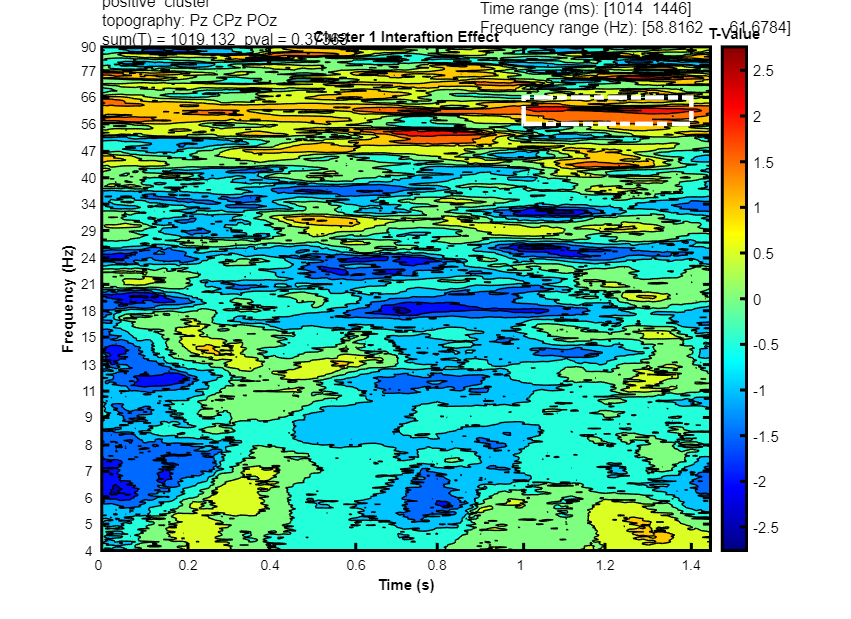


freq_cel_empt = [];freq_cel_empt = find(cellfun(@isempty,freq_cl_tot));
freq_cl_tot(freq_cel_empt) = [];
time_cel_empt = [];time_cel_empt = find(cellfun(@isempty,time_cl_tot));
time_cl_tot(time_cel_empt) = [];
%
i = []; t_range_tot = []; f_range_tot = [];
for i = 1:1:size(t_tot,1) %number of comparisons and clusters 
    j = [];  x = []; x = t_tot(i,6); electrodes = []; 
    %electrodes
    num_elec = []; 
    for j = 1:1:22
        s = []; s = convertCharsToStrings(labels{j,1});
        if contains(x, s)
            electrodo1 = []; electrodo1 = s;
            electrodes = [electrodes; electrodo1]; 
            num_elec = [num_elec;j];
        end
    end
    num_elec_cl{1,i} = num_elec;
    electrodes = join(electrodes');
    elec_clus = [elec_clus;electrodes]; 
    %time range
    t = []; t = time_cl_tot{i,1};
    min_t = []; min_t = min(t); max_t = []; max_t = max(t);
    t_range = []; t_range = [min_t*1000,max_t*1000]; 
    t_range = num2str(t_range);
    t_range_tot = [t_range_tot;convertCharsToStrings(t_range)];
    %freq range
    f = []; f = freq_cl_tot{i,1};
    min_f = []; min_f = min(f); max_f = []; max_f = max(f);
    f_range = []; f_range = [min_f,max_f];  
    f_range = num2str(f_range);
    f_range_tot = [f_range_tot;convertCharsToStrings(f_range)];
end

t_tot(:,7) = elec_clus;
t_tot(:,8) = t_range_tot; t_tot(:,9) = f_range_tot;
% save num_elec_cl_IntEffect.mat num_elec_cl
%%
j = []; i = []; 
for i = 1:1:1%size(t_tot,1)% clusters - Here only one will be plotted
    elect = []; elect = t_tot(i,7); %electrodes for cluster
    if contains(elect, "Cz Pz CPz POz") || contains(elect, "Fz AFz") ...
            ||  contains(elect, "Pz POz") || contains(elect, "Cz Pz CPz")
% select electrodes of interest if needed
        com = []; com =  t_tot(i,1); %comparison
        if com == 'General effect ANOVA - NT-ASD' % Adjust
            numcom = []; numcom = 1;
        end
        m = []; m =  str2num(t_tot(i,2)); %index of cluster
        signclus = []; signclus = t_tot(i,3); %sign of cluster
        sumTplot = []; sumTplot = str2num(t_tot(i,4)); %sumT
        pvalplot = []; pvalplot = str2num(t_tot(i,5)); %p-val
        elect = []; elect = t_tot(i,7); %electrodes of cluster
        time_range = []; time_range = t_tot(i,8); %time range of cluster 
        freq_range = []; freq_range = t_tot(i,9); %freq range of cluster
        num_el = num_elec_cl{1,i};
        par = []; par = IntEffect.stat; %T-val
        %mean over electrodes 
        par_elec = []; par_elec = par(num_el,:,:);
        par_avg_elec = []; par_avg_elec = squeeze(mean(par_elec,1));
        times = []; times = IntEffect.time; %time
        
        figure('WindowState','maximized'); 
    %     imagesc(par_avg_elec);
        contourf(par_avg_elec);
        set(gca,'YDir','normal'); c = colorbar;set(c,'LineWidth',2)
        mi = []; mi = min(min(par_avg_elec)); ma = []; ma = max(max(par_avg_elec));
        if abs(mi) > abs(ma)
           caxis([mi -mi]);
        elseif abs(ma) > abs(mi)
           caxis([-ma ma]);
        else
            caxis([mi ma])
        end
        colorTitleHandle = get(c,'Title');
        titleString = 'T-Value';
        set(colorTitleHandle ,'String',titleString, 'FontWeight', 'bold',...
            'fontname', 'Arial', 'FontSize', 10, 'Color', 'k');
        c.FontName = 'Arial'; c.FontSize = 10; c.Color = 'k';
        c2=jet(230); colormap(c2);
        ax = gca; set(ax,'LineWidth',2)
        labelsY = ax.YAxis.TickLabels; % extract
        idx = []; idx = knnsearch(frequencies', (logspace(0.6,1.96,20))');
        set(ax, 'YTick', idx,'XColor', 'k', 'YColor','k');
        labelsY2 = round(frequencies(idx)); 
        ax.YAxis.TickLabels = labelsY2; % set    
        ax.YAxis.FontName = 'Arial'; ax.YAxis.FontSize = 10; ax.YAxis.Color = 'k';
        ylabel('Frequency (Hz)', 'FontWeight', 'bold', 'fontname', 'Arial',...
            'FontSize', 10,'Color','k')
    
        labelsX = ax.XAxis.TickLabels; % extract
        idx = []; idx = knnsearch(times', [0; 0.2;0.4;0.6;0.8;1;1.2;1.4]);
        set(ax, 'XTick', idx);
        labelsX2 = [0; 0.2;0.4;0.6;0.8;1;1.2;1.4]; 
        ax.XAxis.TickLabels = labelsX2; % set    
        ax.XAxis.FontName = 'Arial'; ax.XAxis.FontSize = 10; ax.XAxis.Color = 'k';
        xlabel('Time (s)', 'FontWeight', 'bold','fontname', 'Arial',...
            'FontSize', 10,'Color','k');
        title(['Cluster ' num2str(i) ' Interaftion Effect']);        
        txt = []; txt = compose(join([signclus " cluster " + "\n" + ...
            "topography: " + elect +  "\n" + ...
        "sum(T) = " + num2str(sumTplot) + "  " + "pval = " + num2str(pvalplot)])); 
        Lgnd = text(1, 483, txt, 'FontSize',10.5); 
        
        txt2 = []; txt2 = compose(join(["Time range (ms): [" + num2str(time_range) + ...
            "]" + "\n" + "Frequency range (Hz): [" + num2str(freq_range)+ "]"])); 
        Lgnd = text(80, 485, txt2, 'FontSize',10.5); 

        % Patch
        freq = []; freq = t_tot(i,9); %freq range for cluster
        time = []; time =  str2num(t_tot(i,8))'/1000; %time range for cluster
        Range = ax.YTick(knnsearch(labelsY2', str2num(freq)'));

        RangeTime = knnsearch([0; 0.2;0.4;0.6;0.8;1;1.2;1.4], time);

        patch([ax.XTick(min(RangeTime)) ax.XTick(max(RangeTime))...
            ax.XTick(max(RangeTime)) ax.XTick(min(RangeTime))], ...
            [Range(1) Range(1) Range(2) Range(2)], ...
            'red','FaceAlpha',0, 'LineStyle', '-.', 'linewidth', 3, ...
            'EdgeColor', 'w')


        set(gcf, 'Position',  [500,100,825,600])
%         exportgraphics(gcf, join([num2str(0) 'Interaftion Effect - ' num2str(m) '_' signclus '_' com  '.tif']),...
%             'Resolution',100)
%         close all
    end
end

**Please, see the R code "*****ANOVA*****" for details about the methodology to assess post-hoc simple main effects (assessing the effect of one factor at each modality of the other factor) and pairwise comparisons when adequate.**